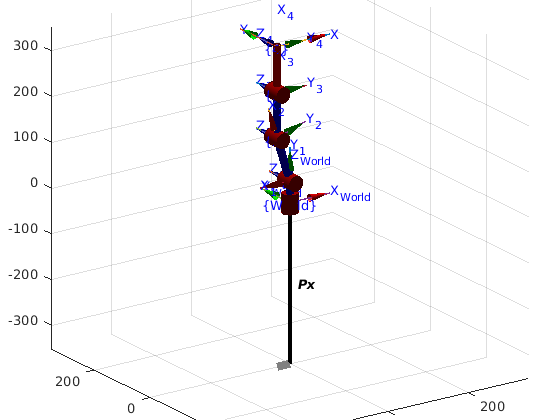

%% Creación modelo Phantom en Matlab empleando parámetros DHstd, modelo mirando hacia la caja de control
% Cálulo de las longitudes de eslabón
    l1 = 47;
    l2 = sqrt(100^2+32^2);
    l3 = 100;
    l4 = 100;
    l = [l1, l2, l3, l4]; 
% Cálculo de offsets
    off1 = pi;%Cambiar a pi si se desea el robot mirando hacia afuera, 0 hacia el controlador
    off2 = atand(100/32)*pi/(180);
    off3 = pi/2-off2;
    off4 = 0; 

%%Limites de los motores 
%%id    rango                       nuehome          Destino  rango
%%1     0       -   4095            2048 - 180       3073     0-360
%%2     1100    -   3300            2048 - 180       2477     
%%3     1000    -   3333            3073 - 270       1925
%%4     600     -   3333            2048 - 180       835
%%5     1550    -   3110 -  3600    3110             2180
                    
% Definicion del robot DH std
    L(1) = Link('revolute','alpha',pi/2, 'a',0,   'd',l(1),'offset',off1, 'qlim',[-pi pi]); %Rango útil -180° a +180°
    L(2) = Link('revolute','alpha',0,    'a',l(2),'d',0,   'offset',off2, 'qlim',[-1.454213787 1.920543946]); %Rango útil -83.320° a 110.039°
    L(3) = Link('revolute','alpha',0,    'a',l(3),'d',0,   'offset',off3, 'qlim',[-3.178408192 0.4003689856]); %Rango útil -182.109° a 22.939°
    L(4) = Link('revolute','alpha',0,    'a',l(4),'d',0,   'offset',off4, 'qlim',[-2.221204181 1.971165312]); %Rango útil -127.266° a 112.939°
    PhantomX = SerialLink(L,'name','Px');
    
% roty(pi/2)*rotz(-pi/2)
PhantomX.tool = [0 0 1 0; 1 0 0 0; 0 1 0 0; 0 0 0 1];


tool = [ 0  0  1  0; 
             1  0  0  0; 
             0  1  0  0;
             0  0  0  1];
    PhantomX.tool = tool; % Ajuste para emplear notación NOA 
    PhantomX.plot([0 0 0 0], 'notiles')
    hold on
    trplot(eye(4),'rgb','arrow','length',100,'frame','World')
    view(-35,20)
%     hold off
    %Revisar marcos coordenados
    q = zeros(1,4);
    M = eye(4);
    for i=1:PhantomX.n
        M = M * L(i).A(q(i));
        trplot(M,'rgb','arrow','frame',num2str(i),'length',75)
    end
    hold off







%%
qt = deg2rad([60, -70, 20, 15]);
Tt = PhantomX.fkine(qt);
%%
% Desacople
T = Tt;
Posw = T(1:3,4) - l(4)*T(1:3,3); % MTH Wrist
%%
% Solucion q1
q1 = atan2(Posw(2),Posw(1));
rad2deg(q1)

ans = -120.0000

%%
% Solución 2R
h = Posw(3) - l(1);
r = sqrt(Posw(1)^2 + Posw(2)^2);

% Codo abajo
the3 = acos((r^2+h^2-l(2)^2-l(3)^2)/(2*l(2)*l(3)));
the2 = atan2(h,r) - atan2(l(3)*sin(the3),l(2)+l(3)*cos(the3));

q2d = -(pi/2-the2);
q3d = the3;

% Codo arriba
% the3 = acos((r^2+h^2-l(2)^2-l(3)^2)/(2*l(2)*l(3)));
the2 = atan2(h,r) + atan2(l(3)*sin(the3),l(2)+l(3)*cos(the3));
q2u = -(pi/2-the2);
q3u = -the3;

disp(rad2deg([q2d q3d; q2u q3u]))

  -87.7447   37.7447
  -50.9545  -37.7447



%%
% Solucion de q4
Rp = (rotz(q1))'*T(1:3,1:3);
pitch = atan2(Rp(3,1),Rp(1,1));

q4d = pitch - q2d - q3d;
q4u = pitch - q2u - q3u;
%disp(rad2deg([q4d q4u]))

qinv(1,1:4) = [q1 q2u q3u q4u];
qinv(2,1:4) = [q1 q2d q3d q4d];
disp(rad2deg(qinv))

 -120.0000  -50.9545  -37.7447  233.6992
 -120.0000  -87.7447   37.7447  195.0000



%%
% Solucion alternativa para q4
T03d = PhantomX.A([1 2 3],[q1 q2d q3d]);
R_3Td = (T03d(1:3,1:3))'*T(1:3,1:3);
% syms q4
% L(4).A(q4)*PhantomX.tool
% [ sin(q4),  0, cos(q4), 9*cos(q4)]
% [-cos(q4),  0, sin(q4), 9*sin(q4)]
% [       0, -1,       0,         0]
% [       0,  0,       0,         1]
q4d = atan2(R_3Td(1,1),-R_3Td(2,1));
rad2deg(q4d)

ans = 85

%%
T03u = PhantomX.A([1 2 3],[q1 q2u q3u]);
R_3Tu = (T03u(1:3,1:3))'*T(1:3,1:3);
q4u = atan2(R_3Tu(1,1),-R_3Tu(2,1));
qinv(1,1:4) = [q1 q2u q3u q4u];
qinv(2,1:4) = [q1 q2d q3d q4d];
disp(rad2deg(qinv))

 -120.0000  -50.9545  -37.7447  123.6992
 -120.0000  -87.7447   37.7447   85.0000



%%

%% Iniciamos nodo ROS
rosinit;

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_92310 with NodeURI http://sara-Lenovo-ideapad-110-14ISK:33339/


%% Definimos el cliente del servicio que vamos a emplear junto a su mensaje
motorSvcClient = rossvcclient('/dynamixel_workbench/dynamixel_command');
motorCommandMsg = rosmessage(motorSvcClient);

Error using feval
Unrecognized function or variable 'ros.msggen.dynamixel_workbench_msgs.DynamixelCommandRequest'.

Error in rosmessage (line 57)
        msg = feval(msgInfo.msgClassGen, msg);

Error in ros.ServiceClient/rosmessage (line 340)
            msg = rosmessage(obj.RequestType, 

%% Vector de posición para el robot
format long G
valores=[0 0 0 0 0];
angulos=valores+[180 180 270 180 273];
posicion=(4096/360)*angulos; 
q=[0 0 0 0 0];
qRobot=q*13.65+2048;
%%Generamos el mensaje deseado antes de llamar al servicio con el cliente
motorCommandMsg.AddrName = "Goal_Position";
motorCommandMsg.Id = 1;
motorCommandMsg.Value = posicion(1);%%rango 0-4096
call(motorSvcClient, motorCommandMsg);
pause(0.5);

motorCommandMsg.AddrName = "Goal_Position";
motorCommandMsg.Id = 2;
motorCommandMsg.Value = posicion(2);%%rango 0-4096
call(motorSvcClient, motorCommandMsg);
pause(0.5);

motorCommandMsg.AddrName = "Goal_Position";
motorCommandMsg.Id = 3;
motorCommandMsg.Value = posicion(3);%%rango 0-4096
call(motorSvcClient, motorCommandMsg);
pause(0.5);

motorCommandMsg.AddrName = "Goal_Position";
motorCommandMsg.Id = 4;
motorCommandMsg.Value = posicion(4);%%rango 0-4096
call(motorSvcClient, motorCommandMsg);
pause(0.5);

motorCommandMsg.AddrName = "Goal_Position";
motorCommandMsg.Id = 5;
motorCommandMsg.Value = posicion(5);%%rango 0-4096
call(motorSvcClient, motorCommandMsg);
pause(0.5);

Error using matlab.graphics.primitive.Transform/set
Invalid value for Matrix property.

Error in SerialLink/animate (line 104)
                            set(h.link(L), 'Matrix', T);

Error in SerialLink/plot (line 300)
    robot.animate(qq);

Th = transl(-32,0,-347)*trotz(0)*troty(0);
T0 = transl(0,-150,0)*trotz(-pi/2)*troty(pi);
T1 = transl(0,-150,-40)*trotz(-pi/2)*troty(pi);
% ctraj
Th0 = ctraj(Th,T0,20);
T01 = ctraj(T0,T1,20);

% ciclo para calcular y graficar el robot
pause(1)
for i=1:20
   qinv = invKinPxC(Th0(:,:,i),l);
   PhantomX.plot(qinv(2,:),'notiles','noname')
   plot3(Th0(1,4,i),Th0(2,4,i),Th0(3,4,i),'ro')
   q_inv(i,:) = qinv(2,:);
   %pause(0.5)
end

pause(1)
for i=1:20
   qinv = invKinPxC(T01(:,:,i),l);
   PhantomX.plot(qinv(2,:),'notiles','noname')
   plot3(T01(1,4,i),T01(2,4,i),T01(3,4,i),'ro')
   q_inv(i,:) = qinv(2,:);
   %pause(0.5)
end